syms S E I R u nu alpha gamma beta B d Ts
dS_dt = B/1000+(nu/10*R)-(((beta+u)*I)/(S+E+I+R))*S-d/1000*S;
dE_dt = (((beta+u)*I)/(S+E+I+R))*S-alpha*E-d/1000*E;
dI_dt = alpha*E-gamma*I-d/1000*I;
dR_dt = gamma*I-nu/10/10*R-d/1000*R;



Model_eqs = [dS_dt; dE_dt; dI_dt; dR_dt]

$$Model\_eqs = \begin{array}{l} \left(\begin{array}{c} \frac{B}{1000}-\frac{S\,d}{1000}+\frac{R\,\nu }{10}-\sigma_{1}\\ \sigma_{1}-\frac{\text{E}\,d}{1000}-\text{E}\,\alpha \\ \text{E}\,\alpha -\frac{\text{I}\,d}{1000}-\text{I}\,\gamma \\ \text{I}\,\gamma -\frac{R\,d}{1000}-\frac{R\,\nu }{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\left(\beta +u\right)}{\text{E}+\text{I}+R+S} \end{array}$$

Discrete_model=Model_eqs*Ts+[S;E;I;R]

$$Discrete\_model = \begin{array}{l} \left(\begin{array}{c} S+\mathrm{Ts}\,\left(\frac{B}{1000}-\frac{S\,d}{1000}+\frac{R\,\nu }{10}-\sigma_{1}\right)\\ \text{E}-\mathrm{Ts}\,\left(\text{E}\,\alpha +\frac{\text{E}\,d}{1000}-\sigma_{1}\right)\\ \text{I}-\mathrm{Ts}\,\left(\frac{\text{I}\,d}{1000}-\text{E}\,\alpha +\text{I}\,\gamma \right)\\ R-\mathrm{Ts}\,\left(\frac{R\,d}{1000}-\text{I}\,\gamma +\frac{R\,\nu }{100}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\left(\beta +u\right)}{\text{E}+\text{I}+R+S} \end{array}$$


A=jacobian(Model_eqs, [S E I R])

$$A = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}-\sigma_{2}-\frac{d}{1000} & \sigma_{1} & \sigma_{1}-\sigma_{3} & \frac{\nu }{10}+\sigma_{1}\\ \sigma_{2}-\sigma_{1} & -\alpha -\frac{d}{1000}-\sigma_{1} & \sigma_{3}-\sigma_{1} & -\sigma_{1}\\ 0 & \alpha & -\frac{d}{1000}-\gamma & 0\\ 0 & 0 & \gamma & -\frac{d}{1000}-\frac{\nu }{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\left(\beta +u\right)}{{\sigma_{4}}^{2}}\\ \sigma_{2}=\frac{\text{I}\,\left(\beta +u\right)}{\sigma_{4}}\\ \sigma_{3}=\frac{S\,\left(\beta +u\right)}{\sigma_{4}}\\ \sigma_{4}=\text{E}+\text{I}+R+S \end{array}$$

Phi=eye(4)+A*Ts

$$Phi = \begin{array}{l} \left(\begin{array}{cccc} 1-\mathrm{Ts}\,\left(\frac{d}{1000}+\sigma_{3}-\sigma_{4}\right) & \sigma_{1} & -\sigma_{2} & \mathrm{Ts}\,\left(\frac{\nu }{10}+\sigma_{4}\right)\\ \mathrm{Ts}\,\left(\sigma_{3}-\sigma_{4}\right) & 1-\mathrm{Ts}\,\left(\alpha +\frac{d}{1000}+\sigma_{4}\right) & \sigma_{2} & -\sigma_{1}\\ 0 & \mathrm{Ts}\,\alpha & 1-\mathrm{Ts}\,\left(\frac{d}{1000}+\gamma \right) & 0\\ 0 & 0 & \mathrm{Ts}\,\gamma & 1-\mathrm{Ts}\,\left(\frac{d}{1000}+\frac{\nu }{100}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\mathrm{Ts}\,\left(\beta +u\right)}{{\sigma_{5}}^{2}}\\ \sigma_{2}=\mathrm{Ts}\,\left(\frac{S\,\left(\beta +u\right)}{\sigma_{5}}-\sigma_{4}\right)\\ \sigma_{3}=\frac{\text{I}\,\left(\beta +u\right)}{\sigma_{5}}\\ \sigma_{4}=\frac{\text{I}\,S\,\left(\beta +u\right)}{{\sigma_{5}}^{2}}\\ \sigma_{5}=\text{E}+\text{I}+R+S \end{array}$$

C=[0 0 0 1];

M0=[C;C*Phi;C*Phi^2;C*Phi^3;C*Phi^4]

rank(M0)

ans = 4


M0=double(subs(M0,[B d alpha gamma beta nu S E I R u Ts],[0.0001 0.0001 0.1 0.1 0.2 0.001 0.1431 0.0092 0.0092 0.8384 0.5 10]))

M0 =          0         0         0    1.0000
         0         0    1.0000    0.9999
         0    1.0000    0.9999    0.9998
    0.0552    0.9907    1.9924    0.9905
    0.1068    1.9838    1.9190    0.9818


cond(M0)

ans = 97.1054


dS_dt = B/1000+(nu/10*R)-(((beta+u)*I)/(S+E+I+R))*S-d/1000*S;
dE_dt = (((beta+u)*I)/(S+E+I+R))*S-alpha*E-d/1000*E;
dI_dt = alpha*E-gamma*I-d/1000*I;
dR_dt = gamma*I-nu/10/10*R-d/1000*R;
dNu_dt = 0

dNu_dt = 0


Model_eqs = [dS_dt; dE_dt; dI_dt; dR_dt;dNu_dt]

$$Model\_eqs = \begin{array}{l} \left(\begin{array}{c} \frac{B}{1000}-\frac{S\,d}{1000}+\frac{R\,\nu }{10}-\sigma_{1}\\ \sigma_{1}-\frac{\text{E}\,d}{1000}-\text{E}\,\alpha \\ \text{E}\,\alpha -\frac{\text{I}\,d}{1000}-\text{I}\,\gamma \\ \text{I}\,\gamma -\frac{R\,d}{1000}-\frac{R\,\nu }{100}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\left(\beta +u\right)}{\text{E}+\text{I}+R+S} \end{array}$$

Discrete_model_param=Model_eqs*Ts+[S;E;I;R;nu]

$$Discrete\_model\_param = \begin{array}{l} \left(\begin{array}{c} S+\mathrm{Ts}\,\left(\frac{B}{1000}-\frac{S\,d}{1000}+\frac{R\,\nu }{10}-\sigma_{1}\right)\\ \text{E}-\mathrm{Ts}\,\left(\text{E}\,\alpha +\frac{\text{E}\,d}{1000}-\sigma_{1}\right)\\ \text{I}-\mathrm{Ts}\,\left(\frac{\text{I}\,d}{1000}-\text{E}\,\alpha +\text{I}\,\gamma \right)\\ R-\mathrm{Ts}\,\left(\frac{R\,d}{1000}-\text{I}\,\gamma +\frac{R\,\nu }{100}\right)\\ \nu \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\left(\beta +u\right)}{\text{E}+\text{I}+R+S} \end{array}$$

A_param=jacobian(Model_eqs, [S E I R nu])

$$A\_param = \begin{array}{l} \left(\begin{array}{ccccc} \sigma_{1}-\sigma_{2}-\frac{d}{1000} & \sigma_{1} & \sigma_{1}-\sigma_{3} & \frac{\nu }{10}+\sigma_{1} & \frac{R}{10}\\ \sigma_{2}-\sigma_{1} & -\alpha -\frac{d}{1000}-\sigma_{1} & \sigma_{3}-\sigma_{1} & -\sigma_{1} & 0\\ 0 & \alpha & -\frac{d}{1000}-\gamma & 0 & 0\\ 0 & 0 & \gamma & -\frac{d}{1000}-\frac{\nu }{100} & -\frac{R}{100}\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\left(\beta +u\right)}{{\sigma_{4}}^{2}}\\ \sigma_{2}=\frac{\text{I}\,\left(\beta +u\right)}{\sigma_{4}}\\ \sigma_{3}=\frac{S\,\left(\beta +u\right)}{\sigma_{4}}\\ \sigma_{4}=\text{E}+\text{I}+R+S \end{array}$$

Phi_param=eye(5)+A_param*Ts

$$Phi\_param = \begin{array}{l} \left(\begin{array}{ccccc} 1-\mathrm{Ts}\,\left(\frac{d}{1000}+\sigma_{3}-\sigma_{4}\right) & \sigma_{1} & -\sigma_{2} & \mathrm{Ts}\,\left(\frac{\nu }{10}+\sigma_{4}\right) & \frac{R\,\mathrm{Ts}}{10}\\ \mathrm{Ts}\,\left(\sigma_{3}-\sigma_{4}\right) & 1-\mathrm{Ts}\,\left(\alpha +\frac{d}{1000}+\sigma_{4}\right) & \sigma_{2} & -\sigma_{1} & 0\\ 0 & \mathrm{Ts}\,\alpha & 1-\mathrm{Ts}\,\left(\frac{d}{1000}+\gamma \right) & 0 & 0\\ 0 & 0 & \mathrm{Ts}\,\gamma & 1-\mathrm{Ts}\,\left(\frac{d}{1000}+\frac{\nu }{100}\right) & -\frac{R\,\mathrm{Ts}}{100}\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{I}\,S\,\mathrm{Ts}\,\left(\beta +u\right)}{{\sigma_{5}}^{2}}\\ \sigma_{2}=\mathrm{Ts}\,\left(\frac{S\,\left(\beta +u\right)}{\sigma_{5}}-\sigma_{4}\right)\\ \sigma_{3}=\frac{\text{I}\,\left(\beta +u\right)}{\sigma_{5}}\\ \sigma_{4}=\frac{\text{I}\,S\,\left(\beta +u\right)}{{\sigma_{5}}^{2}}\\ \sigma_{5}=\text{E}+\text{I}+R+S \end{array}$$

C_param=[0 0 0 1 0];
M0_param=[C_param;C_param*Phi_param;C_param*Phi_param^2;C_param*Phi_param^3;C_param*Phi_param^4;C_param*Phi_param^5];
M0_param=double(subs(M0_param,[B d alpha gamma beta nu S E I R u Ts],[0.0001 0.0001 0.1 0.1 0.2 0.001 0.1431 0.0092 0.0092 0.8384 0.5 10]))

M0_param =          0         0         0    1.0000         0
         0         0    1.0000    0.9999   -0.0838
         0    1.0000    0.9999    0.9998   -0.1677
    0.0552    0.9907    1.9924    0.9905   -0.2515
    0.1068    1.9838    1.9190    0.9818   -0.2883
    0.2104    1.9017    2.8448    0.9645   -0.2810


cond(M0_param)

ans = 289.1500

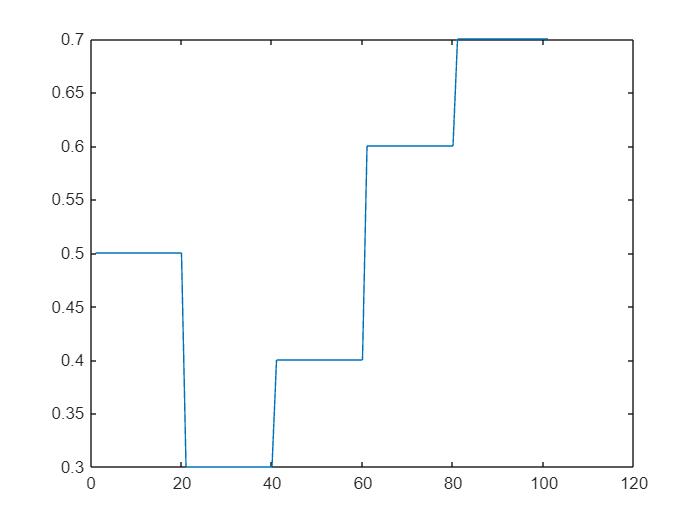

B = 0.334347777716906; %B
d = 0.342692168641646; %d
alpha = 0.0904963402600036; %alpha_
gamma = 0.104149917959794; %gamma_
beta = 0.189760832657602; %beta_dos;
nu = 0.00862168642730242; %nu_
mdl = 'SEIRS_2';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
set_param(path, 'Ruido',1);
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;
T = 1000; % Tiempo máximo de la simulación
Ts = 10; % Período de muestreo definido anteriormente
t = (0:Ts:T)'; % Instantes de simulación
N = length(t);
U = timetable(seconds(t),[0.5*ones(1,(N-1)/5) 0.3*ones(1,(N-1)/5) 0.4*ones(1,(N-1)/5) 0.6*ones(1,(N-1)/5) 0.7*ones(1,(N-1)/5+1)]');
plot(U.Var1)

dir_modelo = "SEIRS_2.slx";
sim_datos_exp=sim(dir_modelo);
x_teo=[sim_datos_exp.S.signals.values'
    sim_datos_exp.E.signals.values'
    sim_datos_exp.I.signals.values'
    sim_datos_exp.R.signals.values'];
y=sim_datos_exp.R.signals.values;





x0 = [S0 E0 I0 R0]';
n = length(x0);
P0 = 0*eye(n);
Q = 0.001*eye(n);
R_k = 0.01^3;

x_act = zeros(n,N);
P_act_traza = zeros(N,1);
K_norma = zeros(N,1);
de_x = zeros(n,N);
N_cond = zeros(N,1);
x_pre = x0;
P_pre = P0;
U=U.Var1;

% Valores de los parámetros estimados
params=zeros(6,1);
params(1) = 0.334347777716906; %B
params(2) = 0.342692168641646; %d
params(3) = 0.0904963402600036; %alpha_
params(4) = 0.104149917959794; %gamma_
params(5) = 0.189760832657602; %beta_dos;
params(6) = 0.00862168642730242; %nu_
C=[0 0 0 1];

syms B d alpha gamma beta nu Ts I R

Ecuaciones del filtro:

for k = 1:N
    % Corrección del estado
    K = P_pre*C'/(C*P_pre*C' + R_k);
    x_act(:,k) = x_pre + K*(y(k) - C*x_pre);
    P_act = (eye(n)-K*C)*P_pre;
    P_act = (P_act + P_act')/2;
    % Actualización del estado para el siguiente paso (i+1)    
    x_pre=double(subs(Discrete_model,[B d alpha gamma beta nu S E I R u Ts],[params(1) params(2) params(3) params(4) params(5) params(6) x_act(1,k) x_act(2,k) x_act(3,k) x_act(4,k) U(k) 10]));
    Phi_num =double(subs(Phi,[B d alpha gamma beta nu S E I R u Ts],[params(1) params(2) params(3) params(4) params(5) params(6) x_act(1,k) x_act(2,k) x_act(3,k) x_act(4,k) U(k) 10]));
    P_pre = Phi_num*P_act*Phi_num' + Q;
    % Vectores con información
    N_cond(k) = cond(obsv(Phi_num,C));
    P_act_traza(k) = trace(P_act);
    K_norma(k) = norm(K);
    de_x(:,k) = sqrt(diag(P_act));
   
end

Cálculo de los residuos:

e_est = y - (C*x_act)';

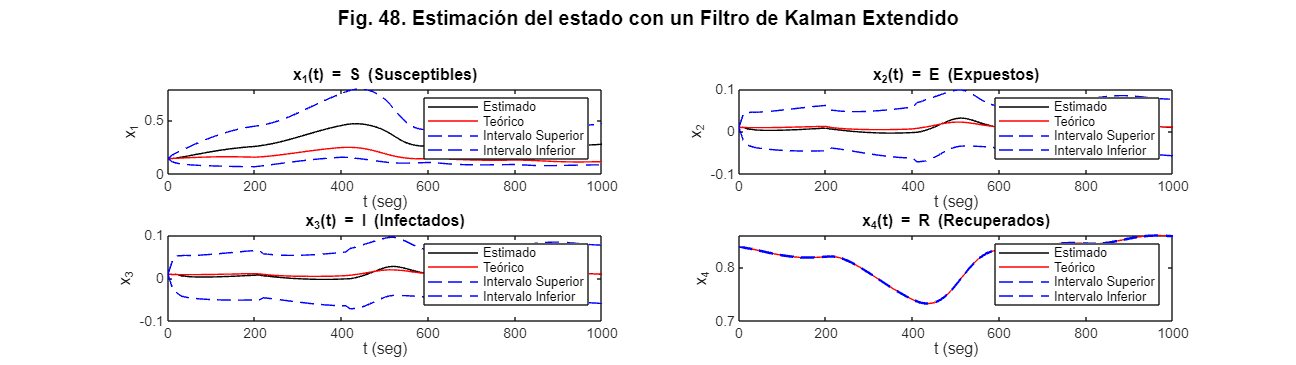


figure('Units','normalized','Position',[0 0 1 0.5])
sgtitle({'Fig. 48. Estimación del estado con un Filtro de Kalman Extendido';''},'FontSize',12,'FontWeight','bold')
x_names = {'S (Susceptibles)', 'E (Expuestos)', 'I (Infectados)', 'R (Recuperados)'};

for k = 1:4
    subplot(2,2,k) % Ajuste para cuatro variables en un arreglo de 2x2
    plot(t, x_act(k,:)','k', ...                     % Estado estimado
         t, x_teo(k,:),'r', ...                     % Estado teórico
         t, (x_act(k,:) + de_x(k,:))','b--', ...    % Intervalo superior
         t, (x_act(k,:) - de_x(k,:))','b--')        % Intervalo inferior
    xlabel('t (seg)')
    ylabel(['x_' num2str(k)])
    title(['x_' num2str(k) '(t) = ' x_names{k}])
    legend({'Estimado', 'Teórico', 'Intervalo Superior', 'Intervalo Inferior'})
end

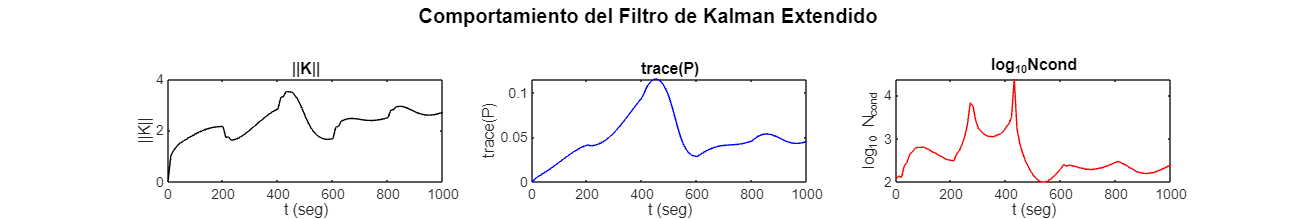

figure('Units','normalized','Position',[0 0 1 0.3])
sgtitle({'Comportamiento del Filtro de Kalman Extendido';''},'FontSize',12,'FontWeight','bold')

subplot(1,3,1)
plot(t, K_norma, 'k')
xlabel('t (seg)'), ylabel('||K||')
title('||K||')

subplot(1,3,2)
plot(t, P_act_traza, 'b')
xlabel('t (seg)'), ylabel('trace(P)')
title('trace(P)')

subplot(1,3,3)
plot(t, log10(N_cond), 'r')
xlabel('t (seg)'), ylabel('log_{10} N_{cond}')
title('log_{10}Ncond')

x0 = [S0 E0 I0 R0 0.005]';
n = length(x0);
P0 = 0*eye(n);
Q = 0.001*eye(n);
R_k = 0.01^3;


x_teo=[sim_datos_exp.S.signals.values'
    sim_datos_exp.E.signals.values'
    sim_datos_exp.I.signals.values'
    sim_datos_exp.R.signals.values';
    ones(1,101).*params(6)];

x_act = zeros(n,N);
P_act_traza = zeros(N,1);
K_norma = zeros(N,1);
de_x = zeros(n,N);
N_cond = zeros(N,1);
x_pre = x0;
P_pre = P0;
C=[0 0 0 1 0];
syms B d alpha gamma beta nu S E I R u Ts
for k = 1:N
    % Corrección del estado
    K = P_pre*C'/(C*P_pre*C' + R_k);
    x_act(:,k) = x_pre + K*(y(k) - C*x_pre);
    P_act = (eye(n)-K*C)*P_pre;
    P_act = (P_act + P_act')/2;
    % Actualización del estado para el siguiente paso (i+1)    
    x_pre=double(subs(Discrete_model_param,[B d alpha gamma beta nu S E I R u Ts],[params(1) params(2) params(3) params(4) params(5) x_act(5,k) x_act(1,k) x_act(2,k) x_act(3,k) x_act(4,k) U(k) 10]));
    Phi_num =double(subs(Phi_param,[B d alpha gamma beta nu S E I R u Ts],[params(1) params(2) params(3) params(4) params(5) x_act(5,k) x_act(1,k) x_act(2,k) x_act(3,k) x_act(4,k) U(k) 10]));
    P_pre = Phi_num*P_act*Phi_num' + Q;
    % Vectores con información
    N_cond(k) = cond(obsv(Phi_num,C));
    P_act_traza(k) = trace(P_act);
    K_norma(k) = norm(K);
    de_x(:,k) = sqrt(diag(P_act));
   
end
e_est = y - (C*x_act)';

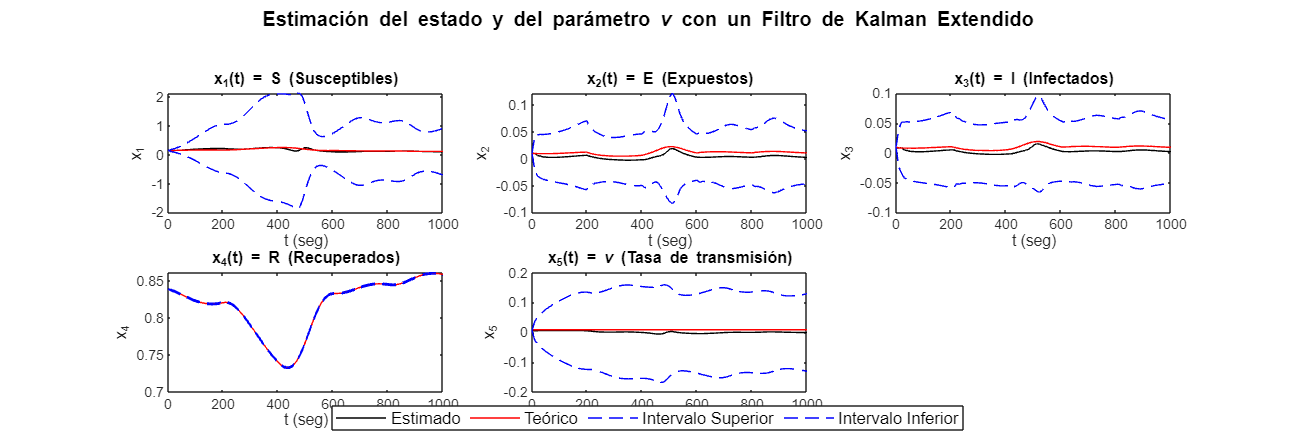


% Figura para las estimaciones de los estados y el parámetro \nu
figure('Units', 'normalized', 'Position', [0 0 1 0.6])
sgtitle({'Estimación del estado y del parámetro \nu con un Filtro de Kalman Extendido'; ''}, 'FontSize', 12, 'FontWeight', 'bold')

% Nombres de las variables
x_names = {'S (Susceptibles)', 'E (Expuestos)', 'I (Infectados)', 'R (Recuperados)', '\nu (Tasa de transmisión)'};

% Crear los subgráficos
for k = 1:5
    subplot(2, 3, k) % Ajuste para cinco variables en un arreglo de 2x3
    plot(t, x_act(k, :)', 'k', ...                  % Estado estimado
         t, x_teo(k, :), 'r', ...                  % Estado teórico
         t, (x_act(k, :) + de_x(k, :))', 'b--', ... % Intervalo superior
         t, (x_act(k, :) - de_x(k, :))', 'b--')     % Intervalo inferior
    xlabel('t (seg)')
    ylabel(['x_' num2str(k)])
    title(['x_' num2str(k) '(t) = ' x_names{k}])
end

% Agregar una leyenda global
hL = legend({'Estimado', 'Teórico', 'Intervalo Superior', 'Intervalo Inferior'}, ...
    'Orientation', 'horizontal', 'FontSize', 10, 'Location', 'southoutside');
hL.Position = [0.4, 0.02, 0.2, 0.05]; % Ajustar la posición manualmente

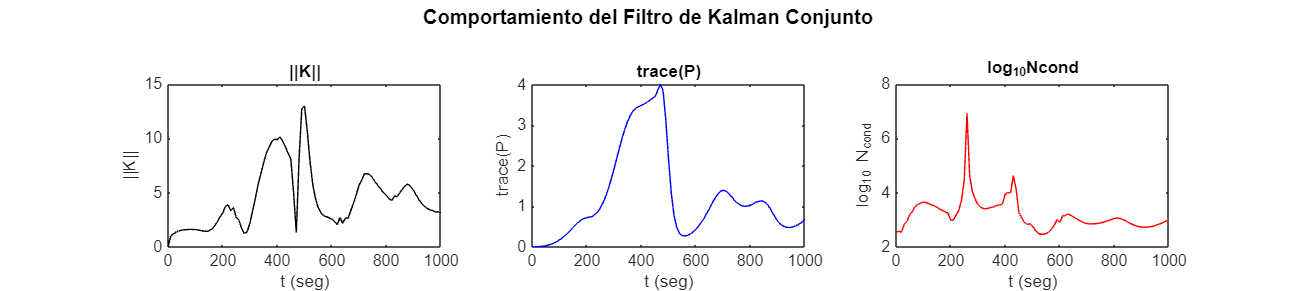



% Figura para el comportamiento del filtro de Kalman
figure('Units', 'normalized', 'Position', [0 0 1 0.4])
sgtitle({'Comportamiento del Filtro de Kalman Conjunto'; ''}, 'FontSize', 12, 'FontWeight', 'bold')

subplot(1, 3, 1)
plot(t, K_norma, 'k')
xlabel('t (seg)'), ylabel('||K||')
title('||K||')

subplot(1, 3, 2)
plot(t, P_act_traza, 'b')
xlabel('t (seg)'), ylabel('trace(P)')
title('trace(P)')

subplot(1, 3, 3)
plot(t, log10(N_cond), 'r')
xlabel('t (seg)'), ylabel('log_{10} N_{cond}')
title('log_{10}Ncond')